table = readtable("../cpp/output/coordinateOutput.csv")

table = 2358×6 table
    simulationID    particleID    depth        x            y          z   
    ____________    __________    _____    _________    _________    ______

         0              0           0              0            0         0
         0              0           0              0            0    2.2764
         0              0           0      -0.023886    -0.027496    4.5525
         0              0           0      -0.024976    -0.025796    6.8289
         0              0           0      -0.097918     0.016978    9.1037
         0              0           0        -0.1732      0.10355    11.377
         0              0           0       -0.24592      0.24282    13.648
         0              0           0       -0.35258      0.40022    15.917
         0    

clf; 

filter = true;
    
% Define marker size
marker_size = 20; % Adjust as needed

if filter
    target =  2;
    filtered2 = table(table.depth == target, :)
    x = filtered2.x;
    y = filtered2.y;
    z = filtered2.z;
else
    x = table.x;
    y = table.y;
    z = table.z;
end

filtered2 = 429×6 table
    simulationID    particleID    depth       x         y         z   
    ____________    __________    _____    _______    ______    ______

         0              42          2       28.224    132.44    321.75
         0              42          2       29.661    132.04    320.03
         0              43          2        31.42    131.35    324.78
         0              43          2       32.469     133.3     325.3
         0              44          2       35.039    128.06    329.49
         0             142          2      -81.793    451.75    390.76
         0             142          2      -82.888     449.8    391.16
         0             142          2      -83.771    447.76    391.66
         0             142          2      -84.689    445.73 

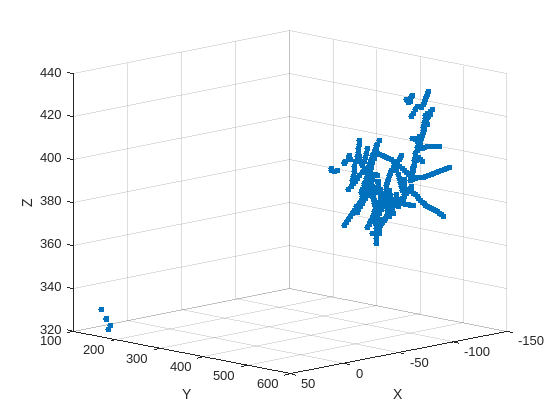


scatter3(x, y, z, marker_size, 'filled')
xlabel("X")
ylabel("Y")
zlabel("Z")
view([3,3,1])
grid on;

% xlim([-150,150])
% ylim([-150,150])
% zlim([0, 1000])